clc;
clear all;

%Number of corners + boolean for answer
numOfParameters = 5;

%How many choices the test taker has
numOfOptions = 4;

%Bounding box threshhold for answer
answerThresh = 30;

%Threshhold to find red marks
bwThresh = .25

bwThresh = 0.2500


%Take in answer key
I1 = imread('original.png');
I2 = imread ('test.jpg');
I3 = imread ('student.png');

% Blank, Answer Key, Student Answers
% Rotate by 90 degrees 
B = rot90(I1);
A = rot90(I2);
S = rot90(I3);



%% Generate answer key


%Get red and green channels
RED = A(:,:,1);
GREEN = A(:,:,2);

%Get only the red marks
I = im2bw(RED - GREEN,bwThresh);

% Close gaps to make sure lines are only detected once. 
se = strel('disk',20);
I = imclose(I,se);
imshow(I);

% Get red blob regions and their properties
[L,numOfBlobs] = bwlabel(I);
props = regionprops(L, 'all');


%Print out the number of questions that we have detected
numOfQuestions= numOfBlobs/numOfOptions;
disp(strcat('Number of Questions detected ', num2str(numOfQuestions)));

Number of Questions detected 3


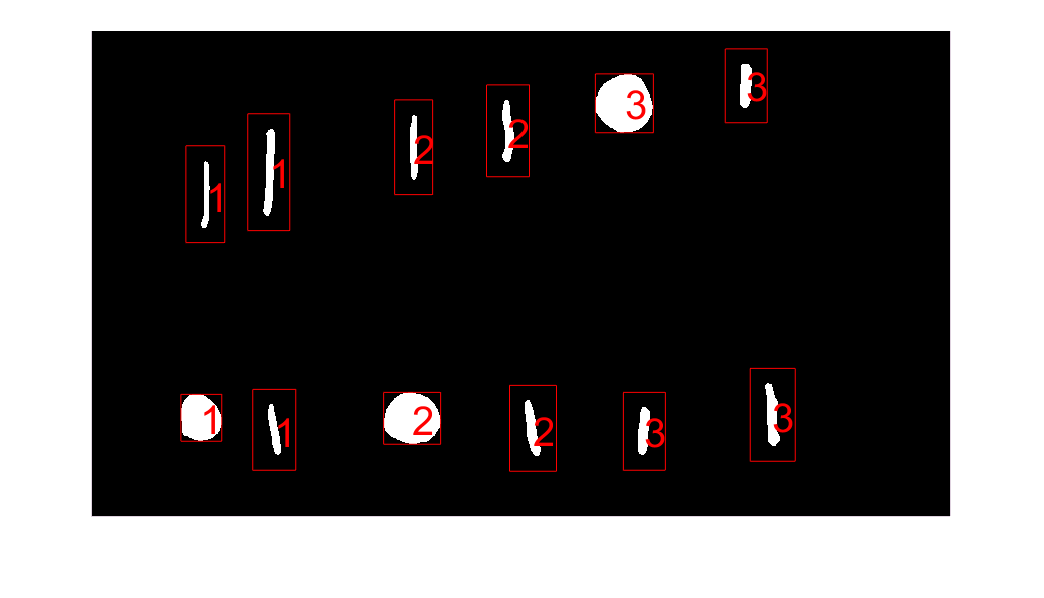



%Initalize array that will hold all questions
questionsArray = zeros(numOfOptions,numOfParameters,numOfQuestions);


%Initialize the question counter and the Question Number
optionNum = 1;
questionNum = 1;

for i=1:numOfBlobs
    % Each region is part of a Question
    if(optionNum > numOfOptions)
        optionNum = 1;
        % Increment Question number every # of options
        questionNum = questionNum +1;
    end
    
    % Get the bounding box for the option
    % Bounding box will be expanded for non-answers
    bb = props(i).BoundingBox;     
    
    % See if it is an answer and then assign a r or g
    % (note: this could also be true of false)
    isAnswer = 0;  
    if(props(i).BoundingBox(3)>answerThresh)
        isAnswer = 1;
    end    
   
    %Add parameters to array if the options are NOT ANSWERS then add additional size to region
    questionsArray(optionNum, numOfParameters, questionNum) = isAnswer;    
    
    moresize = 0;
    if(isAnswer ~= 1)
        moresize = 15;
    end    
    questionsArray(optionNum, 1, questionNum) = bb(1)- moresize;
    questionsArray(optionNum, 2, questionNum) = bb(2)- moresize;
    questionsArray(optionNum, 3, questionNum) = bb(3) + 2*moresize;
    questionsArray(optionNum, 4, questionNum) = bb(4) + 2*moresize;
    
    
    
    % Draw Text and Bounding box
    rectangle('Position',[questionsArray(optionNum, 1, questionNum) questionsArray(optionNum, 2, questionNum) questionsArray(optionNum, 3, questionNum) questionsArray(optionNum, 4, questionNum)],'EdgeColor','r');
    text(props(i).Centroid(1),props(i).Centroid(2),num2str(questionNum),'Color','r',...
       'FontSize',24,'FontWeight','normal');
    
    %Increment option count
    optionNum = optionNum +1;     
   
 end

        
answerKey = questionsArray;
 

%% Marking Portion


